## Plotting Our Contour Map

%neatov2.connect('192.168.16.116');
neatov2.connect() %for simulator

Deleting previous Neato connection.
Connecting to the Neato.


ans =   neatov2 with no properties.


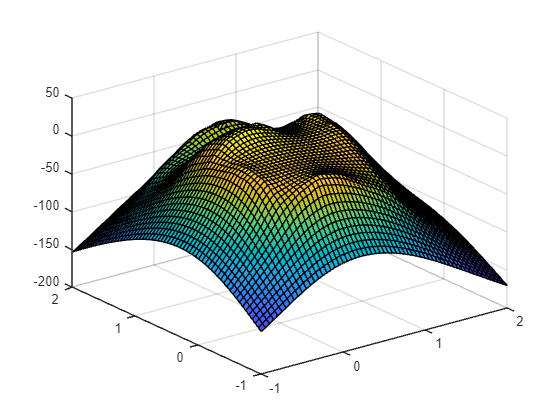


[x,y]=meshgrid(-1:0.05:2,-1:0.05:2); % define the potential at all mesh points

v = 38*log(sqrt((x-0.244).^2+(y-1.128).^2)); % function that defines Bob as sink (put at 35 for vid 4/29)

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
        x_coord = global_points(1,i);
        y_coord = global_points(2,i);
        v = build_equation(v, x, y, x_coord, y_coord); % add source at coordinate          
        i = i + 1;
end

%plot surface
figure();
surf(x, y, v)

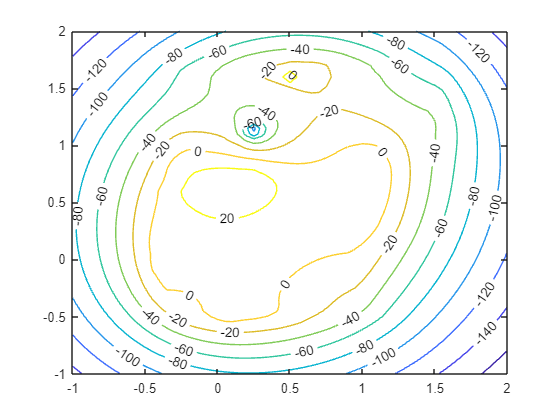


% plot contours with levels marked
figure();
contour(x,y,v,'ShowText','On')

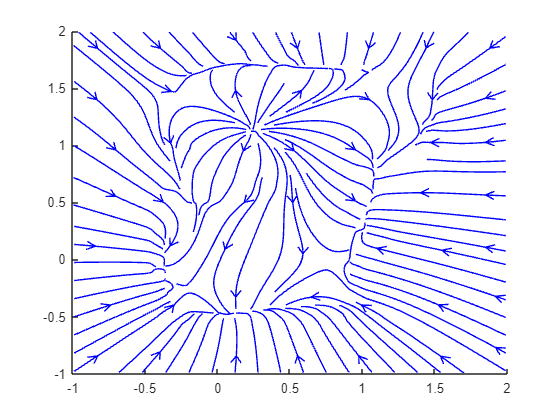

neatov2.setFlatlandContours(x,y,v);

% Vector Field
syms x y

[a, b] = meshgrid(-1:0.05:2, -1:0.05:2);
% flatlands
f = 100 * log(sqrt((x - 0.244).^2 + (y - 1.128).^2));

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

% Iterate through all global points
for i = 1:length(global_points)
    % Extract x, y coordinate pair
    x_coord = global_points(1, i);
    y_coord = global_points(2, i);
    
    % Add contribution from the current global point
    f = build_equation(f, x, y, x_coord, y_coord);
end

% Compute the gradient components symbolically
df_dx = diff(f, x);
df_dy = diff(f, y);

% Convert symbolic expressions to functions
gradient_f_x = matlabFunction(df_dx, 'Vars', {x, y});
gradient_f_y = matlabFunction(df_dy, 'Vars', {x, y});

% Evaluate the functions at specific points
fxn = gradient_f_x(a, b);
fyn = gradient_f_y(a, b);


% Vector Field
figure();
streamslice(a, b,fxn, fyn);

## Finding the Gradient

syms x y

% flatlands
f = 100*log(sqrt((x-0.244).^2+(y-1.128).^2));

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    f = build_equation(f, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

fx = diff(f,x);
fy = diff(f,y);
gradient = [fx, fy];

## Implementing the Gradient

%Starting position and orientation
startingx = 0;
startingy = 0;
startingTheta = 0;

%Parameters
%lambda = 0.0000000005;
linearWheelV = 0.1;

%While loop parameters
i = 2;
i_max = 27; %had at 19 for vid

%Initial position and gradient
r_0 = [startingx; startingy]; %First coordinate
r_list(:,1) = r_0;
r = r_0;

grad = double(subs(gradient, {x, y}, {r(1), r(2)}));
% neatov2.setPositionAndOrientation(startingx,startingy,startingTheta) %simulator

orientation = startingTheta;

while i < i_max && norm(grad) > 0.5
    grad = (double(subs(gradient, {x, y}, {r(1), r(2)})))';
    % CHANGE FOR #6: make lambda proportional to the gradiant
    norm(grad);
    lambda = 0.00004*norm(grad); % default lambda
    if norm(grad) > 190 % adjust lambda for extra steep steps
        lambda = 0.0000005*norm(grad); %0.0000005 for vid
            if norm(grad) > 500 % adjust lambda for extra steep steps
                lambda = 0.00000005*norm(grad); %0.0000005 for vid
                if norm(grad) > 500 % adjust lambda for extra steep steps
                    lambda = 0.000000025*norm(grad); %0.0000005 for vid
                end
            end
    end
    next_r = r - lambda*grad;
    vectorDiff = next_r-r;
    newOrientation = atan2(vectorDiff(2),vectorDiff(1));

    
    deltaTheta = newOrientation-orientation;
    angularV = 0.1/0.254;
    spinTime = abs(deltaTheta/angularV);
    neatov2.driveFor(spinTime, sign(deltaTheta)*-0.05, sign(deltaTheta)*0.05, true); %true for sim
    pause(.01)

    distance = norm(vectorDiff);
    % CHANGE FOR #6: if distance of path is insignificant, end the loop
    if distance < 0.0025
        break
    end
    driveTime = distance/linearWheelV;
    neatov2.driveFor(driveTime, linearWheelV, linearWheelV, true)  %true for sim 

    %%FOR NON-SIMULATED%%
    % pause(.01)

    r = next_r;
    r_list(:,i) = r(1,:);
    i = i + 1;

    orientation = newOrientation; 
end

## Helper Functions

function [v] = build_equation(v, x, y, x_coord, y_coord)
% Add new source to equation evaluted at meshgrid.
%
% Inputs
%   v (square matrix): Equation evaluted at meshgrid
%   x (square matrix): X coordinates of meshgrid
%   y (square matric): Y coordinates of meshgrid
%   x_coord (float): X coordinate of source
%   y_coord(float): Y coordinate of source
%
% Returns
%   v (square matrix): Newly built equation evaluted at meshgrid

    v = v - 0.16 * (log(sqrt((x-x_coord).^2+(y-y_coord).^2))); %had at 0.1 for vid 4/29
end
